clear;
close all
mex  ./pesq/*.c -output ./bin/PESQ_MEX

使用 'MinGW64 Compiler (C)' 编译。
MEX 已成功完成。


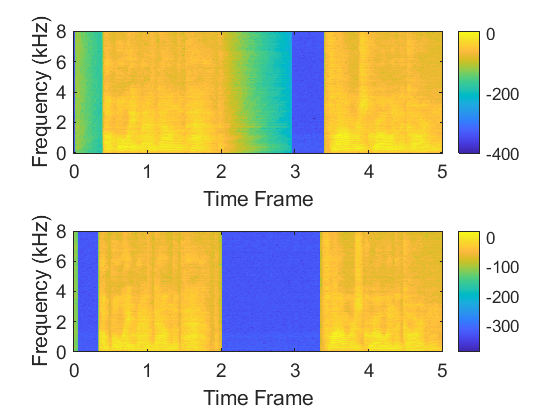

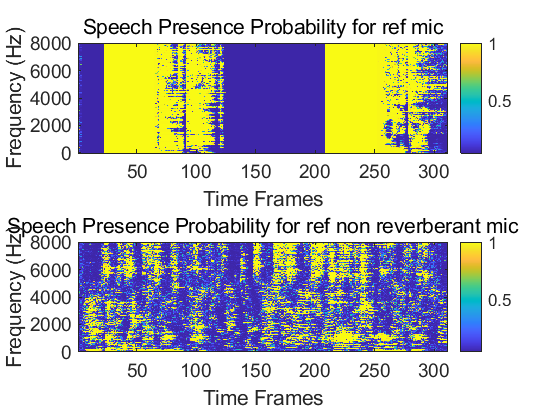

if ispc
    addpath('..\..\audio_files');
    addpath('..\..\sim_environment');
    addpath('.\pesq');
    addpath('.\bin');
else
    addpath('../../audio_files');
    addpath('../../sim_environment');
    addpath('../pesq-mex-master');
end

%%

% Generate speech signal
% Load ATFs
load Computed_RIRs
% load speech_both 
source_filename{1} = 'speech1.wav';
siglength = 5; 
num_mics = 2;
[source_signals_raw{1}, source_signals_raw{2}] = audioread(source_filename{1});
signal  = resample(source_signals_raw{1},fs_RIR,source_signals_raw{2});
signal = 10*signal(1:siglength*fs_RIR);
speech = fftfilt(RIR_sources,signal,siglength*fs_RIR);
he = zeros(size(RIR_sources,1),size(RIR_sources,2)); 
he(1:800,:) = RIR_sources(1:800,:);
hr = zeros(size(RIR_sources,1),size(RIR_sources,2)); 
hr(801:end,:) = RIR_sources(801:end,:);
speech_e = fftfilt(he,signal,siglength*fs_RIR);
speech_r = fftfilt(hr,signal,siglength*fs_RIR);
% % generate HRTF signal % HRTF is reveb, larger distortion
% load HRTF
% speech = fftfilt(HRTF(1:600,:),signal,siglength*fs_RIR); 
% % generate non reveb signal, with non reveb noise , has 44 dB snr, least
% % distortion
% load binaural_sig  % non reverbration speech signal
% speech = binaural_sig(1:fs_RIR*siglength,:);

% Generate noise at microphone
 SNR_bubble = 5; 
 SNR_white = 300;
noise_filename{1} = 'Babble_noise1.wav';noise_filename{2} = 'White_noise1.wav';

noise_babble = generate_noise(noise_filename{1},speech(:,1),fs_RIR,...
    SNR_bubble,RIR_noise,siglength);
noise_white  = generate_noise(noise_filename{2},speech(:,1),fs_RIR,...
    SNR_white,RIR_noise,siglength);



%% Exercise 3.1: ## Obtain the noisy microphone signals as outlined in the session document.
%
% SOME CONVENTIONS:
%
% Your clean speech signal should be called "speech" and is a binaural signal such that:
% speech = [speech_L speech_R]  % speech_L and speech_R are the clean binaurally synthesised speech signals from session 1
%
% Your noises should be stored in one binaural variable called "noise"


noise = noise_white + noise_babble;
% noise = noise_babble;
% Create noisy mic signals in the time domain:
noisy_sig = speech + noise ;  %  stacked microphone signals


%soundsc(y_TD,fs_RIR)
snrb = snr(speech(:,1),noise_babble(:,2));
snrw = snr(speech(:,1),noise_white(:,2));
%% Apply WOLA analysis to observe signals in the STFT domain, Apply the SPP.

fs = fs_RIR;    % sampling freq
nfft = 512;    % number of DFT points
window = sqrt(hann(nfft,'periodic')); % analysis window
noverlap = 2;   % factor for overlap. noverlap = 2 corresponds to 50% overlap
time = 0:1/fs:((size(speech,1)-1)/fs);


% ## Apply the WOLA analysis to the noisy mic. signals, the speech, and the noise.
%  reveberation
[y_STFT,f] = WOLA_analysis(noisy_sig,fs_RIR,window,nfft,noverlap) ;% To complete
[n_STFT,~] = WOLA_analysis(noise,fs_RIR,window,nfft,noverlap) ;% To complete
[x_STFT,~] = WOLA_analysis(speech,fs_RIR,window,nfft,noverlap) ;% To complete
[xe_STFT,~] = WOLA_analysis(speech_e,fs_RIR,window,nfft,noverlap) ;% To complete
[xr_STFT,~] = WOLA_analysis(speech_r,fs_RIR,window,nfft,noverlap) ;% To complete
% Observe the STFT
clow = -100; chigh = 10; % lower and upper limits for signal power in spectrogram (can change for different resolutions)
[N_freqs, N_frames] = size(y_STFT(:,:,1));

figure;subplot(2,1,1);
imagesc(time, f/1000, mag2db(abs(xr_STFT(:,:,1)))); colorbar;
axis xy; set(gca,'fontsize', 14);
set(gcf,'color','w'); xlabel('Time Frame'); ylabel('Frequency (kHz)')
subplot(2,1,2);
imagesc(time, f/1000, mag2db(abs(xe_STFT(:,:,1)))); colorbar;
axis xy; set(gca,'fontsize', 14);
set(gcf,'color','w'); xlabel('Time Frame'); ylabel('Frequency (kHz)')
% figure;
% imagesc(time, f/1000, mag2db(abs(y_STFT_rev(:,:,1))), [clow, chigh]); colorbar;
% axis xy; set(gca,'fontsize', 14);
% set(gcf,'color','w'); xlabel('Time Frame'); ylabel('Frequency (kHz)')



%%
% ## Compute the Speech Presence Probability on the reference microphone
% (you can try the speech-only signal or the noisy-speech in one of the microphones)
% Use the attached spp_calc.m function

[noisePowMat_y, SPP_y] =  spp_calc(noisy_sig(:,1),nfft,nfft/noverlap);% To complete
[noisePowMat, SPP] =  spp_calc(speech_e(:,1),nfft,nfft/noverlap);
% [noisePowMat_e, SPP_e] =  spp_calc(speech_e(:,1),nfft,nfft/noverlap);
% % Observe the SPP
figure; subplot(2,1,1);
imagesc(1:N_frames, f,SPP); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Speech Presence Probability for ref mic');
subplot(2,1,2);
imagesc(1:N_frames, f,SPP_y); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Speech Presence Probability for ref non reverberant mic');
% %%
% % 
% %% observe Tx_mask, TY_mask, TN_mask
TY_Mask = zeros(N_freqs,N_frames);
TX_Mask = zeros(N_freqs,N_frames);
TXE_Mask = zeros(N_freqs,N_frames);
TN_Mask = zeros(N_freqs,N_frames);
noise_spl = zeros(N_freqs,N_frames);
NMR = zeros(N_freqs,N_frames);

for t = 1:N_frames
%  use 1st mic speech signal as masker
%      [TY_Mask(:,t),bark] = mask_cal(y_STFT(:,t,1),f,fs,nfft,t,1);
   [TX_Mask(:,t),bark] = mask_cal(x_STFT(:,t,1),f,fs,nfft,t,5);
   noise_spl(:,t) = psd2spl(n_STFT(:,t,1),nfft);
   NMR(:,t) = noise_spl(:,t)-TX_Mask(:,t);          
end

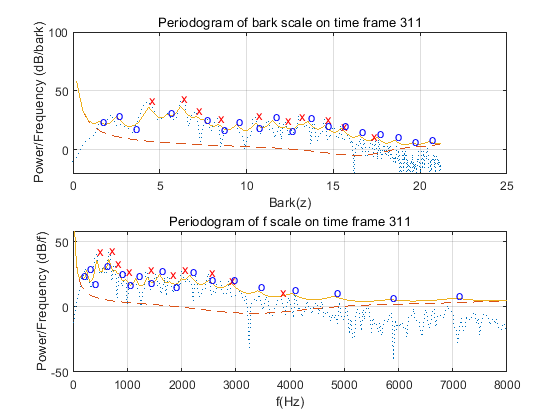

for t = 1:N_frames
%  use 1st mic non reverbrant speech signal as masker
   [TY_Mask(:,t),bark] = mask_cal(y_STFT(:,t,1),f,fs,nfft,t,10);
   noise_spl(:,t) = psd2spl(n_STFT(:,t,1),nfft);
   NMR(:,t) = noise_spl(:,t)-TXE_Mask(:,t);          
end

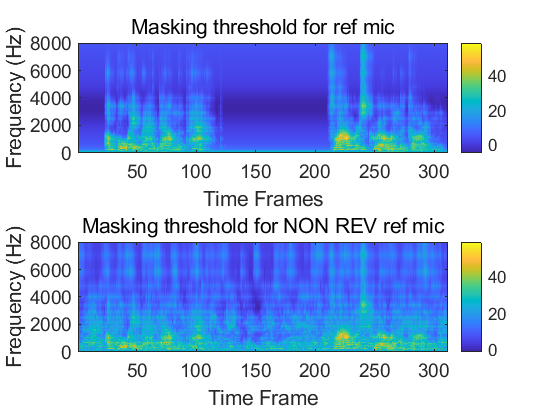

% Observe the TM
figure; subplot(2,1,1);
imagesc(1:N_frames, f,TX_Mask); colorbar; axis xy; set(gcf,'color','w');
set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Masking threshold for ref mic');
subplot(2,1,2);
imagesc(1:N_frames, f, TY_Mask); colorbar;
axis xy; set(gca,'fontsize', 14);
set(gcf,'color','w'); xlabel('Time Frame'); ylabel('Frequency (Hz)'),...
title('Masking threshold for NON REV ref mic');

% figure;
% imagesc(1:N_frames, f,NMR); colorbar; axis xy; set(gcf,'color','w');
% set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('NMR');



%%  Exercise 3.2: ## Implementation of the MWF

% % calculate RTF d and diffuse reverberation gama
[h_steer,gama] = RTF_cal(fs_RIR,m_pos,s_pos,num_mics,N_freqs) ;

Rnn = cell(N_freqs,1);  Rnn(:) = {1e-9*randn(num_mics,num_mics)};      % Noise Only (NO) corr. matrix. Initialize to small random values
Ryy = cell(N_freqs,1);  Ryy(:) = {1e-9*randn(num_mics,num_mics)};      % Speech + Noise (SPN) corr. matrix. Initialize to small random values
Rxx = cell(N_freqs,1);  Rxx(:) = {1e-9*randn(num_mics,num_mics)};      % esitimated speech corr. matrix. Initialize to small random values                                                                                                                                       
Rxx_real = cell(N_freqs,1);  Rxx_real(:) = {1e-9*randn(num_mics,num_mics)};      % esitimated speech corr. matrix. Initialize to small random values                                                                                                                                       
Rxx_esti = cell(N_freqs,1);  Rxx_esti(:) = {1e-9*randn(num_mics,num_mics)};      % esitimated speech corr. matrix. Initialize to small random values                                                                                                                                       

model.lambda = 0.8;                                                       % Forgetting factors for correlation matrices - can change
model.SPP_thr = 0.5;                                                       % Threshold for SPP - can change
model.alpha = 0.33;
% For MWF filter for left ear
S_mvdr_mwfL_stft = zeros(N_freqs,N_frames,num_mics);
X_mvdr_mwfL_stft = zeros(N_freqs,N_frames,num_mics);
N_mvdr_mwfL_stft = zeros(N_freqs,N_frames,num_mics);
W_mvdr_mwfL = (1/num_mics)*ones(num_mics,N_freqs,num_mics);
weight = (1/num_mics)*ones(num_mics,N_freqs,N_frames);
K = ones(N_freqs,num_mics,N_frames);alpha = 0.09;
rho_s = zeros(N_freqs,N_frames);
rho_r = zeros(N_freqs,N_frames);
% STFT Processing
% Looping through each time frame and each frequency bin
% SPP = zeros(257,311);
% SPP(:,23:115) = 1; SPP(:,213:311) = 1;
% tic
for l=1:N_frames % Time index
    for k = 2:N_freqs % Freq index
                
        % Create a vector of mic. signals
        Y_kl = squeeze(y_STFT(k,l,1:num_mics));  % M x 1 noisy mic sigs for this freq and time frame
        X_kl = squeeze(x_STFT(k,l,1:num_mics));
        N_kl = squeeze(n_STFT(k,l,1:num_mics));
        % ## Update the correlation matrices using the forgetting factor.
        % Threshold the SPP in order to distinguish between periods of speech and non-speech activity
        if(SPP(k,l)>model.SPP_thr)
             Ryy{k} = model.lambda*Ryy{k}+(1-model.lambda).* Y_kl* Y_kl';
            % speech + noise
        else
            % noise only
             Rnn{k} = model.lambda*Rnn{k}+(1-model.lambda).* Y_kl* Y_kl'; % N*N' is not available in real situation 
             Ryy{k} = Rnn{k};
        end           
            Rxx_real{k} = (model.alpha*Rxx_real{k}+(1-model.alpha).* X_kl* X_kl');
%         % model.Rx choose which model to estimate Rx, 1: real update 
%         % 2: direct estimate 3: decesion directed 
%            if (abs(Ryy{k}(1,1))> abs(Rnn{k}(1,1)))
%            Rxx_esti{k} = Ryy{k};
%            else
%            Rxx_esti{k} = 0.01*Rnn{k}(1,1);
%            end
%            Rxx{k} = Rxx_real{k};
%            [vector,eigen] = eig(Rxx{k});
%            eigen(find(eigen<0)) = 0;
%            Rxx_remove0{k} = pinv(vector')* eigen* pinv(vector);
%            L = chol(gama{k});
%            [~,lamada] = eig(inv(L) *  Rxx_remove0{k} * inv(L'),'vector');
%           
%            if k<81
%                rho_rev_realx(k,l) = lamada(2)/300 ;
%            else
%                rho_rev_realx(k,l) = lamada(2);
%            end
%            
% %             rho_s_esti(k,l) = Rxx_esti{k}(1,1)-rho_rev_realx(k,l);
%             if(l>1) 
%                 residual = rho_s (k,l-1);
%             else
%                 residual = 0;
%             end
%         rho_s (k,l) = (1-model.alpha)*xe_STFT(k,l,1).^2 +model.alpha*residual;
            if(l>1) 
                residual_r = rho_r (k,l-1);
            else
                residual_r = 0;
            end
        rho_r (k,l) = (1-model.alpha)*xr_STFT(k,l,1).^2 +model.alpha*residual_r;
%         
%         a = 0.6;  
%       noise_power = abs(n_STFT(k,l,1))^2;
% %       noise_power = noisePowMat_y(k,l);
%       postSNR(k,l) = abs(y_STFT(k,l,1))^2/noise_power;
%      if l==1 ;resi = 0;else ;resi = Rx3(k,l-1)/noise_power; end
%       prioiSNR(k,l) = a * resi +(1-a)*max(0,postSNR(k,l)-1);
%       % mmse
%       sig_spectral = (prioiSNR(k,l)/(1+prioiSNR(k,l)))*y_STFT(k,l,1);
%       % another method
% %       mu = 1;
% %       sig_spectral = sqrt(prioiSNR(k,l)/(mu+prioiSNR(k,l)))*()
%       Rx3(k,l) = sig_spectral*conj(sig_spectral);
%        % calculate mu used in SDW MWF     
%        % mu1: fix constant; mu2 spp model; mu3 psycho1;mu4 psycho2
       model.mu = 1;
       mu = mu_calc(SPP(k,l),TX_Mask(k,l),NMR(k,l),model.mu);
       muxx(k,l) =  mu;  
%        % calculate W_update in different model ,func =1:4
%        model.weight = 3; model.power = 1;
% %       
%        [W_update,mvdr_n1(k,l),mvdr_n2(k,l)] = weight_cal(Ryy{k}, Rnn{k},Rxx{k},rho_rev_realx(k,l),...
%                Rx2(k,l),TX_Mask(k,l),gama{k},h_steer(:,k),model.power,model.weight,mu);  
%       
       model.weight = 4;model.power = 1;
 [W_update,mvdr_n1(k,l),mvdr_n2(k,l)] = weight_cal(Ryy{k}, Rnn{k},Rxx{k},1,...
               1,TY_Mask(k,l),gama{k},h_steer(:,k),model.power,model.weight,mu);  
     

       weight(:,k,l) =W_update;  
       % update w
         for m = 1:num_mics    
              % After experiments, we found that Filter parameter is not likely
              % larger than 2 if it converges.
            if(max(abs(W_update)) < 2.2) % This will skip some initial frames  
                W_mvdr_mwfL(:,k,m) =W_update;              
            end
            % Filtering the noisy speech, the speech-only, and the noise-only.
            S_mvdr_mwfL_stft(k,l,m) = W_mvdr_mwfL(:,k,m)'* Y_kl(1:num_mics);
            X_mvdr_mwfL_stft(k,l,m) = W_mvdr_mwfL(:,k,m)'* X_kl(1:num_mics);
            N_mvdr_mwfL_stft(k,l,m) = W_mvdr_mwfL(:,k,m)'* N_kl(1:num_mics);
        end
        
        
    end % end freqs
end % end time frames
% toc;


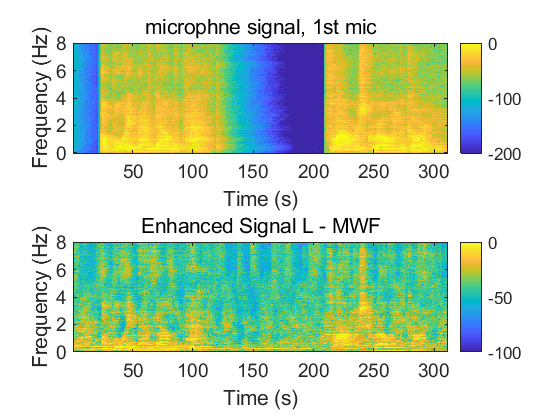

% Observe processed STFTst

figure; subplot(2,1,1);
imagesc(1:N_frames,f/1000,mag2db(abs(x_STFT(:,:,1))),[-200 0]); colorbar; axis xy; set(gcf,'color','w');set(gca,'Fontsize',14); xlabel('Time (s)'), ylabel('Frequency (Hz)'), title('microphne signal, 1st mic');
S_L_enhanced = S_mvdr_mwfL_stft(:,:,1);
subplot(2,1,2); imagesc(1:N_frames,f/1000, ...
    mag2db(abs(S_mvdr_mwfL_stft(:,:,1))),[-100 0]); 
colorbar; axis xy; set(gcf,'color','w');set(gca,'Fontsize',14);
xlabel('Time (s)'), ylabel('Frequency (Hz)'),title('Enhanced Signal L - MWF');

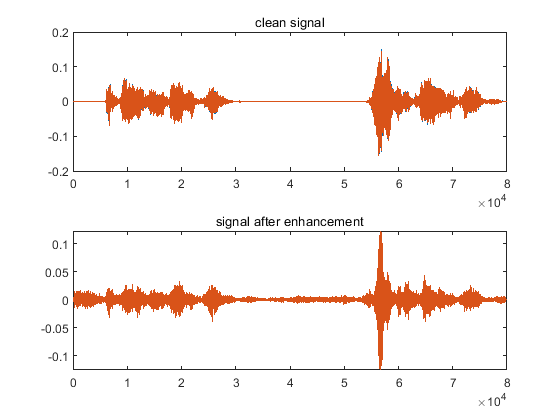

% figure;
% imagesc(1:N_frames, f,muxx); colorbar; axis xy; set(gcf,'color','w');
% set(gca,'Fontsize',14), xlabel('Time Frames'), ylabel('Frequency (Hz)'), title('Masking threshold for ref mic');

% Apply the synthesis stage of the WOLA framework to obtain the time domain equivalents:

s_mwfL = WOLA_synthesis(S_mvdr_mwfL_stft,window,nfft,noverlap);% To complete (time-domain version of S_mvdr_mwfL_stft)
x_mwfL = WOLA_synthesis(X_mvdr_mwfL_stft,window,nfft,noverlap);% To complete (time-domain version of X_mvdr_mwfL_stft)
n_mwfL = WOLA_synthesis(N_mvdr_mwfL_stft,window,nfft,noverlap);% To complete (time-domain version of N_mvdr_mwfL_stft)


% PLOT SIGNALS
figure;
subplot(2,1,1);
plot(speech); title('clean signal');
subplot(2,1,2);
plot(real(s_mwfL));title('signal after enhancement');


% LISTEN TO SIGNALS!
soundsc(real(s_mwfL(:,1)),fs);
% soundsc(signal,fs);
%  soundsc(noisy_sig,fs_RIR);
% EVALUATION
enhance_sig = real(s_mwfL(:,1));
noisy_sig_ref = noisy_sig(:,1);
speech_ref = speech_e(:,1);
%  snr
in.snr =snr(speech(:,1),noise(:,1)); % Compute input SNR
out.snr =snr(s_mwfL(:,1),n_mwfL(:,1)) ;% Compute output SNR
delta.SNR_L = out.snr-in.snr;
% segsnr
% [in.segsnr,in.glosnr]=v_snrseg(noisy_sig_ref,speech_ref,fs,'Vq',0.03); 
% [out.segsnr,out.glosnr]=v_snrseg(real(s_mwfL),speech_ref,fs,'Vq',0.03); 
% delta.segSNR = out.segsnr-in.segsnr;
% spectral distance SD
[in.SD,in.BSD,in.MBSD] = distor_cal(x_STFT,y_STFT,nfft,TX_Mask);
[out.SD,out.BSD,out.MBSD] = distor_cal(x_STFT,S_mvdr_mwfL_stft,nfft,TX_Mask);
delta.SD = out.SD-in.SD; delta.BSD = out.BSD-in.BSD; delta.MBSD = out.MBSD-in.MBSD; 
in.sd = mean(v_disteusq(x_STFT,y_STFT,'d'));
out.sd = mean(v_disteusq(x_STFT,S_mvdr_mwfL_stft,'d'));
delta.sd = out.sd - in.sd;
% PESQ
in.pesq = pesq_mex(speech_ref, noisy_sig_ref, fs, 'wideband');

Perceptual Evaluation of Speech Quality (PESQ)

done.
done.
 Level normalization...
 IRS filtering...
 Variable delay compensation...
 Acoustic model processing...

P.862.2 Prediction (MOS-LQO):  = 1.357


out.pesq = pesq_mex(speech_ref, enhance_sig, fs, 'wideband');

Perceptual Evaluation of Speech Quality (PESQ)

done.
done.
 Level normalization...
 IRS filtering...
 Variable delay compensation...
 Acoustic model processing...

P.862.2 Prediction (MOS-LQO):  = 1.409


delta.pesq = out.pesq - in.pesq;
% STOI short time objective Intelligibility Measure
in.stoi  = stoi(speech_ref,noisy_sig_ref, fs);
out.stoi = stoi(speech_ref, enhance_sig, fs);
delta.stoi = out.stoi - in.stoi;
% display 
% disp(deltapesq)
% disp(['delta_SNR = ', num2str(delta_segSNR),' pesq',num2str(delta_pesq),' ,SD_L is ', num2str(SD_L),...
%     ' ,BSD_L is ', num2str(BSD_L), ' ,MBSD is ', num2str(MBSD_L), ' ,weight model is ',num2str(model.weight) ,' ,mu model is ',num2str(model.mu)]);
% 
delta

delta = 包含以下字段的 struct :
    SNR_L: 5.6350
       SD: -0.6646
      BSD: -0.0025
     MBSD: -398.4119
       sd: 8.9264
     pesq: 0.0529
     stoi: -0.0138
